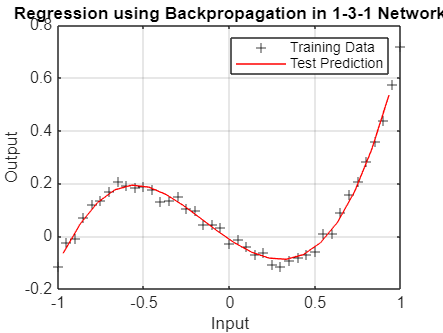

clear;
clc;

% Training data input x
x = -1:0.05:1;
len = length(x);

% Training data output y, with added noise
d = 0.8*x.^3 + 0.3*x.^2 - 0.4*x + normrnd(0, 0.02, [1, len]);

% Network Parameters
learning_rate = 0.01;
epochs = 100000;
phi_hidden = @(x) tanh(x); % Activation function for hidden layer
phi_hidden_derivative = @(x) 1 - tanh(x).^2; % Derivative of tanh

% Weights & Bias Initialization
w11 = randn * 0.1;
w12 = randn * 0.1;
w13 = randn * 0.1;

w_11 = randn * 0.1;
w_21 = randn * 0.1;
w_31 = randn * 0.1;

% Biases for hidden and output layer, initialized with small values
xb1 = randn * 0.1;
xb2 = randn * 0.1;
xb3 = randn * 0.1;
xb_o = randn * 0.1;

% Training the neural network using SGD
for epoch = 1:epochs
    for i = 1:len
        % Forward Propagation
        input = x(i);
        desired = d(i);

        % Hidden Layer Calculations
        v_1_1 = w11 * input + xb1;
        v_2_1 = w12 * input + xb2;
        v_3_1 = w13 * input + xb3;

        hidden_output1 = phi_hidden(v_1_1);
        hidden_output2 = phi_hidden(v_2_1);
        hidden_output3 = phi_hidden(v_3_1);

        % Output Layer Calculations
        v_1_2 = w_11 * hidden_output1 + w_21 * hidden_output2 + w_31 * hidden_output3 + xb_o;
        y1 = v_1_2; % Linear activation function at output

        % Error Calculation
        error = desired - y1;

        % Backpropagation (Output to Hidden Layer)
        delta_output = error; % Derivative of linear output is 1
        w_11 = w_11 + learning_rate * delta_output * hidden_output1;
        w_21 = w_21 + learning_rate * delta_output * hidden_output2;
        w_31 = w_31 + learning_rate * delta_output * hidden_output3;
        xb_o = xb_o + learning_rate * delta_output;

        % Backpropagation (Hidden Layer to Input)
        delta_hidden1 = delta_output * w_11 * phi_hidden_derivative(v_1_1);
        delta_hidden2 = delta_output * w_21 * phi_hidden_derivative(v_2_1);
        delta_hidden3 = delta_output * w_31 * phi_hidden_derivative(v_3_1);

        % Update weights and biases for the hidden layer
        w11 = w11 + learning_rate * delta_hidden1 * input;
        w12 = w12 + learning_rate * delta_hidden2 * input;
        w13 = w13 + learning_rate * delta_hidden3 * input;

        xb1 = xb1 + learning_rate * delta_hidden1;
        xb2 = xb2 + learning_rate * delta_hidden2;
        xb3 = xb3 + learning_rate * delta_hidden3;
    end
end

% Testing the network with unseen test data
x_test = -0.97:0.1:0.93;
len_test = length(x_test);
predicted = zeros(1, len_test);

for i = 1:len_test
    % Hidden layer calculations for test data
    v_1_1 = w11 * x_test(i) + xb1;
    v_2_1 = w12 * x_test(i) + xb2;
    v_3_1 = w13 * x_test(i) + xb3;

    hidden_output1 = phi_hidden(v_1_1);
    hidden_output2 = phi_hidden(v_2_1);
    hidden_output3 = phi_hidden(v_3_1);

    % Output layer calculation for test data
    v_1_2 = w_11 * hidden_output1 + w_21 * hidden_output2 + w_31 * hidden_output3 + xb_o;
    predicted(i) = v_1_2;
end

% Plotting the results
figure;
plot(x, d, 'k+', 'DisplayName', 'Training Data');
hold on;
plot(x_test, predicted, 'r-', 'DisplayName', 'Test Prediction');
legend;
title('Regression using Backpropagation in 1-3-1 Network');
xlabel('Input');
ylabel('Output');
grid on;